## **5-band Equalizer**

E3DSB Miniprojekt 3. Marc, Søren, Janus.

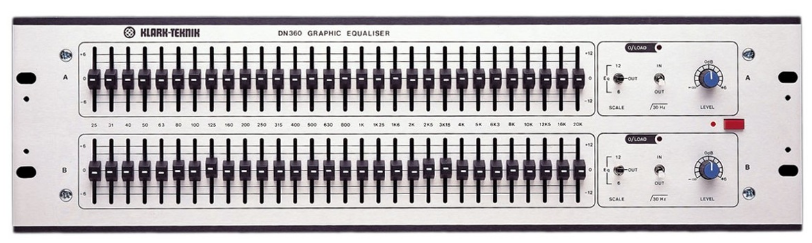

### 1. Formål

Formålet med dette miniprojekt er at implementere en 5-bånds-equalizer i Matlab, herunder at udvælge, designe og implementere FIR og IIR filtre. Design af filtre til brug af mennesker er tilsyneladende lige så meget en kunst som en videnskab, så dette miniprojekt er bare et sjovt forsøg på at anvende lidt teori og at eksperimentere med resultaterne.

### 2. Krav

- 5 frekvensbånd over det hørbare område.

- Niveau justeres med +/- 12 dB.

- Skal benytte både FIR- og IIR-filtre.

- Serie af bånd skal være: LP, BP, BP, BP, HP.

### 3. Analyse

Da der kræves 5 frekvensbånd i equalizeren, skal der benyttes 5 forskellige filtre til at separere det oprindelige signal i 5 forskellige komponenter, hver med sit eget "sub-bånd". Vi skal altså udvikle en simpel filterbank, hvor hvert filter har en overføringsfunktionfunktion, der udskiller hver sin komponent fra den samlede båndbredde. Vi forestiller os altås en parallel struktur.

Nedenstående blokdiagram viser, hvordan vi forestiller os opbygning af equalizeren.

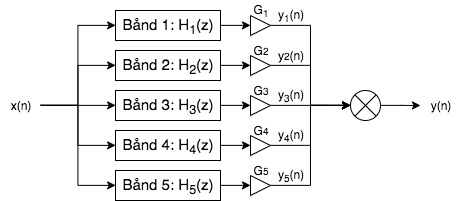

#### 3.1 Valg af båndbredde og centerfrekvens for filtrene

Det hørbare område er ca. 20 Hz til 20 kHz [1]. For mennesker fungerer hørelsen dog logaritmisk [2]. Dvs. en matematisk lineært stigende frekvens (eller lydtryk) vil *ikke *opleves som en lineær udvikling. En logaritmisk stigende frekvens (eller lydtryk) *vil *derimod opleves som en lineær udvikling (og en mere behagelig sekvens). 

Det giver altså mening at opdele det hørbare område efter logaritmisk skala, som bestående af ca. 10 oktaver (1 oktav = 1 fordobling i frekvens). Hvert bånd kan da repræsentere 2 oktaver, altså en udvikling med faktor $2^2 =4$ per bånd. Til sammenligning har equalizeren på forsiden 30 bånd, med ca. 1/3 oktav i afstand. 

Vi vælger altså en startfrekvens til første bånd, og lader den udvikle sig med en faktor 4. Nedenstående tabel opsummerer båndene til vores equalizer:

low_freq = 20*4.^(0:4);
high_freq = low_freq * 4;
center_freq = 0.5*(low_freq + high_freq);
bands = [low_freq; high_freq; center_freq];
names = {'Low limit [Hz]';'High limit [Hz]';'Center freq. [Hz]'};
headers = {'Bands_1_5'};
t = table(bands); t.Properties.RowNames = names; t.Properties.VariableNames = headers

t = 3×1 table
                                       Bands_1_5               
                         ______________________________________

    Low limit [Hz]       20       80      320     1280     5120
    High limit [Hz]      80      320     1280     5120    20480
    Center freq. [Hz]    50      200      800     3200    12800


#### 3.2 Valg af filtertyper til de forskellige bånd

Det er et krav, at equalizeren indeholder både FIR- og IIR-filtre. Herunder vurderes filtrenes fordele og ulemper, og disse sammenholdes med vores "use case".

**FIR-filtre:**

- (+) Lineær faserespons, dvs. ingen forvrængning fra ikke-lineær faserespons el. group-delay.

- (+) Altid garanteret stabilitet.

- (-) Kræver væsentligt højere orden af filter end IIR til at opnå samme performance (roll-off, m.v.).

- (-) Det kan være svært at få god performance ud af et FIR-filter, selv med høj orden (N > 1000).

- (-) Ikke optimalt til filtrering i real-tid, grundet mange beregninger i højere-ordensfiltre.

***Læringer efter at have eksperimenteret med filterDesigner i et par timer:*** Det er temmelig svært at designe et ordentligt FIR-filter i BP, som har et skarpt roll-off... Og det tager irritererende lang tid at filtrere et helt musikstykke med et >1000-ordens-filter... Selv ved højere orden er der fremtrædende sidelobes, der påvirker frekvensresponset og derfor opfattelsen af lyden. Så vi må se og nødsaget til at revurdere tilgangen. 

**IIR-filtre:**

- (+) God performance kan opnås med relativt lav orden af filteret, lav beregningsmængde.

- (+) Kan nemt benyttes til filtrering i real-tid.

- (-) Skal være opmærksom på filterets stabilitet. Stabilitet skal sikres i design.

- (-) Risiko for forvrængning pga. ikke-lineær faserespons.

***Læringer efter eksperimenter:*** Der er høj værdi i at få et filter af lav orden, så beregninger kan foretages hurtigt - selv på noget så "simpelt" som et musiknummer. Der er tilsyneladende større værdi i et skarpt roll-off og ingen sidelobes (IIR), end der er i lineær faseforskydning (FIR). -> Vi går efter flere IIR-filtre.

**Trade-off:**

Vi har altså et trade-off mellem de to filter-typer. Overordnet for vores "use case":

- Vi filtrerer et stykke musik, der allerede er i "hukommelsen", og skal ikke filtrerere i real-tid -> FIR OK.

- Vi har rigelig regnekraft i vores maskiner -> Ingen grund til at undlade FIR-filtre af høj orden.

- Vi gider ikke høre på forvrænget musik -> nej tak til IIR :)

***Læringer efter eksperimenter:*** Vi bliver nødt til at bruge IIR, hvis vi gerne vil lytte til vores musik i dag (og ikke først i morgen...!).

**Båndpas vs. LP og HP i "enderne":**

Kravene til equalizer foreskriver hhv. LP og BP i "enderne". I ovenstående tabel, er det tydeliggjort, hvor grænserne til det hørbare spektrum går. 

Når vi implementerer med hhv. LP og BP, vil første bånd inkludere 0-80 Hz.  Centerfrekvensen er derfor 40 Hz, og ikke 50 Hz som i tabellen. 

Ligeledes i den høje ende, hvor frekvenser højere end 20480 Hz kommer med. Der er frekvenser op til halvdelen af samplingsfrekvensen, dvs. op til$0\ldotp 5\cdot 44100\;\mathrm{Hz}=22050\;\mathrm{Hz}$ for typiske digitale lydklip. Centerfrekvensen for det høje bånd rykker sig derfor marginalt opad.

**Sammenfatning:**

Så overordnet set bør vi til vores "use case" bruge flest IIR-filtre af forholdsvis lav orden for at få relativt hurtige beregninger og god roll-off performance. Dog er det et krav, at vi benytter et FIR-filter. Så vi placerer det, hvor det gør "mindst skade", hvilket er i enden af det hørbare spektrum.Vi benytter altså et FIR-filter til HP, som alligevel er et meget "bredt" bånd, og derfor ikke ødelægges voldsomt af at have en lidt bredere transitionsregion.

Tabellen nedenfor opsummerer hvorledes vores equalizer kan opbygges:

types = {'IIR LP', 'IIR BP', 'IIR BP', 'IIR BP', 'FIR HP'};
freq = array2table([center_freq' low_freq' high_freq']);
headers = {'Filtertype', 'Centerfrekvens', 'Nedre', 'Oevre'};
t = [types' freq];
t.Properties.VariableNames = headers

t = 5×4 table
    Filtertype    Centerfrekvens    Nedre    Oevre
    __________    ______________    _____    _____

     'IIR LP'            50           20        80
     'FIR BP'           200           80       320
     'FIR BP'           800          320      1280
     'FIR BP'          3200         1280      5120
     'IIR HP'         12800         5120     20480


Det kan bemærkes, at vi (i vores ideelle analyse), intet overlap eller mellemrum har mellem de 5 bånd. Da roll-off ikke er ideel, da der forventeligt er side-lobes, og da der sker dæmpning allerede i yderkanterne af hvert bånd, får vi ikke en ideel reproduktion af det oprindelige signal til sidst, når signalkomponenterne samles igen. Under design vil det ses, hvor slemt dette problem er.

#### 3.3 Skalering af lydniveau i hvert frekvensbånd

Lydniveauet af hvert bånd skal ifølge krav kunne skaleres op og ned med +/- 12 dB. Dette gøres, som vist i blokdiagrammet ovenfor, ved skalering med en konstant (vist som en forstærker i blokdiagrammet). Dette virker, da vi har med LTI-systemer at gøre, og vi kan tage lineære kombinationer af signalkomponenterne (superposition, osv.).

Konvertering fra en forstærkning i dB til en gain-faktor kan foretages med formlen $G_{\mathrm{dB}} =20\cdot {\mathrm{log}}_{10} \left(G\right)\Rightarrow G={10}^{\frac{G_{\mathrm{dB}} }{20}}$. Matlab har dog en smart funktion, `db2mag`, som vi kan benytte til at foretage omregning. 

#### 3.4 Mixer til sammensætning af endeligt outputsignal

Det endelige signalkomponenter kan, efter forstærkning mixes sammen igen. Mixing sker ved sammenlægning (sum) af de 5 frekvenskomponenter. Sammen med skaleringen ovenfor er equalizerens output, y(n), altså en lineær kombination af de filtrerede signalkomponenter.

### 4. Design

Filterdesign foretages med Matlab FilterDesigner, baseret på ovenstående tabel for båndbredder (båndgrænser) og filtertyper. For IIR filtrene er det yderligere nødvendigt at sikre, at filtrene er stabile (alle poler inden for enhedscirklen i z-planet). Dette bekræftes i filterDesigner.

#### 4.1 FilterDesigner

Fra FilterDesigneren genereres kode til hvert af de 5 filtre. Der skal designes 1 LP (IIR), 3 BP (IIR), og 1 HP (FIR). Detaljerne ses nedenfor.

**4.1.1 Lavpasfilter**

Design udføres efter følgende parametre:

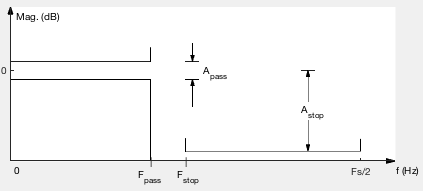

Vi designer et IIR-filter, elliptisk metode (equiripple). IIR, 0-80 Hz. Pass-band vælges 10% under båndets grænse på 80 Hz.

Fs = 44100;                     % Sampling Frequency, as in the Metallica track ;)
Fpass = high_freq(1)*0.9;       % Passband Frequency, 10% below band limit
Fstop = high_freq(1);           % Stopband Frequency, at band limit
Apass = 1;                      % Passband Ripple (dB), max 1 dB.
Astop = 80;                     % Stopband Attenuation (dB), 80 dB down.
match = 'both';                 % Band to match exactly

% Construct an FDESIGN object and call its ELLIP method.
h  = fdesign.lowpass(Fpass, Fstop, Apass, Astop, Fs);
LP = design(h, 'ellip', 'MatchExactly', match);

**4.1.2 Båndpasfiltre**

Design udføres efter følgende parametre:

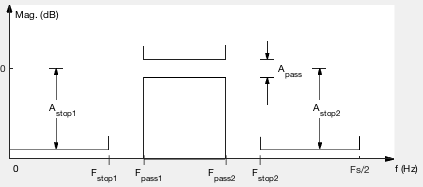

Vi designer de tre BP-filtre efter samme metode (der er værdi i genbrug). Vi benytter den elliptiske model.

**BP1 (IIR, 80-320 Hz):**

Fs = 44100;  % Sampling Frequency

Fstop1 = low_freq(2);           % First Stopband Frequency
Fpass1 = low_freq(2)*1.1;       % First Passband Frequency, +10%
Fpass2 = high_freq(2)*0.9;      % Second Passband Frequency, -10%
Fstop2 = high_freq(2);          % Second Stopband Frequency
Astop1 = 80;                    % First Stopband Attenuation (dB)
Apass  = 1;                     % Passband Ripple (dB)
Astop2 = 80;                    % Second Stopband Attenuation (dB)
match  = 'both';                % Band to match exactly

% Construct an FDESIGN object and call its ELLIP method.
h  = fdesign.bandpass(Fstop1, Fpass1, Fpass2, Fstop2, Astop1, Apass, ...
                      Astop2, Fs);
BP1 = design(h, 'ellip', 'MatchExactly', match);

**BP2 (IIR, 320-1280 Hz):**

Fs = 44100;  % Sampling Frequency

Fstop1 = low_freq(3);           % First Stopband Frequency
Fpass1 = low_freq(3)*1.1;       % First Passband Frequency, +10%
Fpass2 = high_freq(3)*0.9;      % Second Passband Frequency, -10%
Fstop2 = high_freq(3);          % Second Stopband Frequency
Astop1 = 80;                    % First Stopband Attenuation (dB)
Apass  = 1;                     % Passband Ripple (dB)
Astop2 = 80;                    % Second Stopband Attenuation (dB)
match  = 'both';                % Band to match exactly

% Construct an FDESIGN object and call its ELLIP method.
h  = fdesign.bandpass(Fstop1, Fpass1, Fpass2, Fstop2, Astop1, Apass, ...
                      Astop2, Fs);
BP2 = design(h, 'ellip', 'MatchExactly', match);

**BP3 (IIR, 1280-5120 Hz):**

Fs = 44100;  % Sampling Frequency

Fstop1 = low_freq(4);           % First Stopband Frequency
Fpass1 = low_freq(4)*1.1;       % First Passband Frequency, +10%
Fpass2 = high_freq(4)*0.9;      % Second Passband Frequency, -10%
Fstop2 = high_freq(4);          % Second Stopband Frequency
Astop1 = 80;                    % First Stopband Attenuation (dB)
Apass  = 1;                     % Passband Ripple (dB)
Astop2 = 80;                    % Second Stopband Attenuation (dB)
match  = 'both';                % Band to match exactly

% Construct an FDESIGN object and call its ELLIP method.
h  = fdesign.bandpass(Fstop1, Fpass1, Fpass2, Fstop2, Astop1, Apass, ...
                      Astop2, Fs);
BP3 = design(h, 'ellip', 'MatchExactly', match);

**4.1.3 Højpasfilter**

Design udføres efter følgende parametre:

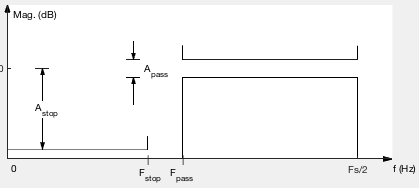

**FIR HP, 5120-... Hz, efter Equiripple-metode.**

Fs = 44100;  % Sampling Frequency

Fstop = low_freq(5);            % Stopband Frequency
Fpass = low_freq(5)*1.1;        % Passband Frequency
Dstop = 0.0001;                 % Stopband Attenuation, 80 dB down
Dpass = 0.057501127785;         % Passband Ripple, 1 dB
dens  = 20;                     % Density Factor

% Calculate the order from the parameters using FIRPMORD.
[N, Fo, Ao, W] = firpmord([Fstop, Fpass]/(Fs/2), [0 1], [Dstop, Dpass]);

% Calculate the coefficients using the FIRPM function.
b  = firpm(N, Fo, Ao, W, {dens});
HP = dfilt.dffir(b);

#### 4.2 Udførte eksperimenter

Liste over hvad vi har prøvet af:

- Forskellige modeller - og observeret sidelobes, magnitude response, roll-off, mv.

- Forskellige ordener, for at få føling med trade-off på FIR-filtre.

- Varieret bredden på transition region, for at få føling med indflydelse på ordenen. 10% transition region fra den definerede grænse virker nogenlunde rimeligt.

### 5. Implementering og test

Implementering og test køres her i samme step, da vi benytter et livescript.

Vi tester equalizeren på vore yndlingsnummer, Metallica's Spit Out the Bone :-)

[x, fs] = audioread('Metallica_Spit_Out_The_Bone.mp4');

Inputsignalet filtreres med de 5 filtre i filterbanken:

y1 = filter(LP, x);
y2 = filter(BP1, x);
y3 = filter(BP2, x);
y4 = filter(BP3, x);
y5 = filter(HP, x);

Gain for de fem bånd sættes ved følgende sliders, der er begrænset mellem -12 og 12 [dB], med stepstørrelse 1. 

G_dB = zeros([5 1]); % Benyttes til at holde gains i dB for alle 5 bånd
G_dB(1) = 0;
G_dB(2) = 0;
G_dB(3) = 0;
G_dB(4) = 0;
G_dB(5) = 0;

Gain i dB konverteres til en gainfaktor, der kan benyttes i filterbanken. 

G = db2mag(G_dB); % konverterer fra dB til gainfaktor

Output fra hvert filter i filterbanken skaleres med gainfaktor og mixes sammen.

y = y1*G(1) + y2*G(2) + y3*G(3) + y4*G(4) + y5*G(5);

Vi kan nu lytte til musikken, efter den har været en tur i equalizeren...

soundsc(y, fs);
pause(10);
clear sound;

Det er desværre tydeligt, at kvaliteten af musikken er forringet lidt. 

Grunden til dette, kan ses i frekvensresponset for hele equalizeren.

### 6. Impuls og frekvensrespons for Equalizeren

close all;

Equalizeren er som nævnt en parallel struktur, og med Matlab-funktionen `dfilt.parallel` kan flere filtre adderes parallelt [3].

Eq = dfilt.parallel(LP, BP1, BP2, BP3, HP); % Sammensætter den parallelle struktur

Vi kan se frekvens og faserespons for equalizeren med `freqz og phasez `(funktioner til digitale filtre, derfor -`z`) [4]:

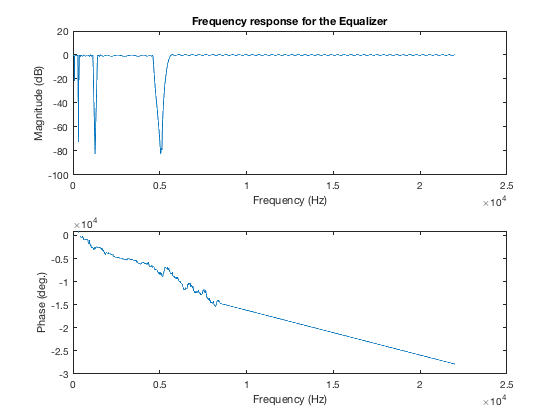

[h, f] = freqz(Eq, 1024, fs); % Frequency response of a digital filter
figure(1)
subplot(2,1,1)
plot(f,20*log10(abs(h)))
ax = gca;
ax.YLim = [-100 20];
title('Frequency response for the Equalizer')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
subplot(2,1,2)
[p, f] = phasez(Eq, 1024, fs);
plot(f,p*180/pi)
xlabel('Frequency (Hz)')
ylabel('Phase (deg.)')

Impulsresponset for den parallelle struktur kan findes med `impz` [5]:

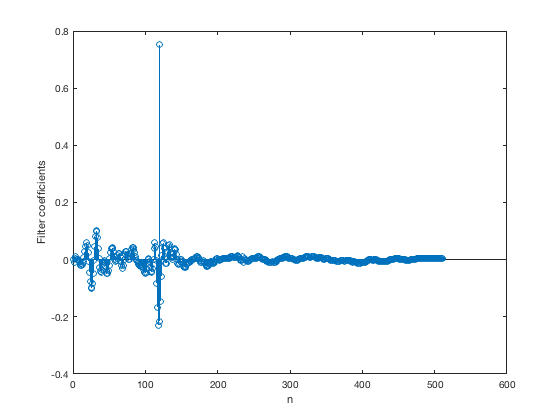

figure(2)
[h, n] = impz(Eq, 512); %Vi plotter kun de første 512, da yderligere ikke giver meget ekstra information her.
stem(n, h);
ylabel('Filter coefficients')
xlabel('n')

**Delkonklusion:**

På frekvensresponset, første plot, ses, at der er "huller" - dvs. frekvensområder, der ikke er kommer med i equalizerens output. Dvs. der er en forringelse af lydsignalet grundet tab af information. Desuden kan det ses, at der er "ripples" i responset, hvilket naturligvis giver noget forvrængning.

På impulsresponset ses filteres "koefficienter". ***Ideelt set***, var equalizeren så "god", at $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack$, og impulsresponset derfor det samme som for en unity buffer, dvs. $h\left\lbrack n\right\rbrack =\left\lbrace 1,0,0,0,0,0,\dots \;\right\rbrace =\delta \left\lbrack n\right\rbrack$. Dette er helt åbenlyst ikke tilfældet, da equalizeren ikke er perfekt, men indeholder både "døde" frekvensområder og forvrængning. Equalizeren består primært af IIR-filtre, men det er vanskeligt (umuligt?) at oversætte impulsresponset til feedforward og feedback-koefficienter.

### 7. Forbedringsmuligheder

Følgende forbedringsmuligheder er overvejet i løbet af projektet.

- Pænere frekvensrespons:

- -> Lukning af hullerne mellem båndene?

- -> Overlap af båndene?

- Analysere faserespons:

- -> Bedre filtre med mindre fase-forvrængning.

- -> Rette op på ulige faserespons fra forskellige filtre, så faseforskydning er ens på tværs af alle filtre.

- Øge hastigheden:

- -> Sænke ordenen på filtrene.

- -> Finde bedre beregningsmetoder. Mere teori.

- Andre eksperimenter:

- -> Filtrere anden slags musik med anden karakter.

- -> Afprøve ikke-musik, forskellige lyde.

- -> Indsætte effekter i equalizeren.

### 8. Konklusion

Vi har i dette mikroprojekt analyseret, designet og implementeret en equalizer, til at opfylde de krav, stillet i opgaven.

Der er væsentlige muligheder for at eksperimentere, når der skal designes filtre til musik, og afgørelser for trade-offs er ligesåmeget en kunst som en videnskab - for i sidste ende handler filteretes kvalitet om, hvordan et givent menneske vil opfatte signalet.

I løbet af dette projekt blev især IIR-filtertypens styrker tydeliggjort for os, da dette projekt (selv med et kort lydklip i normal kvalitet) pludselig viste sig beregningstungt. Højere-ordens FIR-filtre sænker beregningshastigheden væsentligt, og dermed også hastigheden hvormed man kan designe, eksperimentere og re-designe sine filtre.

### 9. Litteratur

[1]: [https://en.wikipedia.org/wiki/Hearing_range#Humans](https://en.wikipedia.org/wiki/Hearing_range#Humans)

[2]: [https://www.audiocheck.net/soundtests_nonlinear.php](https://www.audiocheck.net/soundtests_nonlinear.php)

[3]: [https://www.mathworks.com/help/signal/ref/dfilt.parallel.html](https://www.mathworks.com/help/signal/ref/dfilt.parallel.html)

[4]: [https://www.mathworks.com/help/signal/ref/freqz.html?s_tid=doc_ta](https://www.mathworks.com/help/signal/ref/freqz.html?s_tid=doc_ta)

[5]: [https://www.mathworks.com/help/signal/ref/impz.html?s_tid=doc_ta](https://www.mathworks.com/help/signal/ref/impz.html?s_tid=doc_ta)